% 创建示例数据
[x, y, z] = peaks(30);

% 创建3D图
figure;
surf(x, y, z);
hold on;

% 设置轴属性
xlabel('X轴');
ylabel('Y轴');
zlabel('Z轴');
title('3D图上的固定位置文字标注示例');
grid on;

% 设置光源
light('Position', [15 15 10], 'Style', 'infinite');

% 创建固定位置的文字标注
dim = [0.2 0.8 0.1 0.1]; % [x, y, width, height] 相对于figure的归一化坐标
str = '固定位置标注';
a = annotation('textbox', dim, 'String', str, 'FitBoxToText', 'on', 'BackgroundColor', 'white', 'FontSize', 12, 'FontWeight', 'bold', 'EdgeColor', 'none');
t = text(2,2,10,'随动标注');

t =   Text (随动标注) - 属性:

                 String: '随动标注'
               FontSize: 10
             FontWeight: 'normal'
               FontName: 'Helvetica'
                  Color: [0 0 0]
    HorizontalAlignment: 'left'
               Position: [2 2 10]
                  Units: 'data'

  显示 所有属性


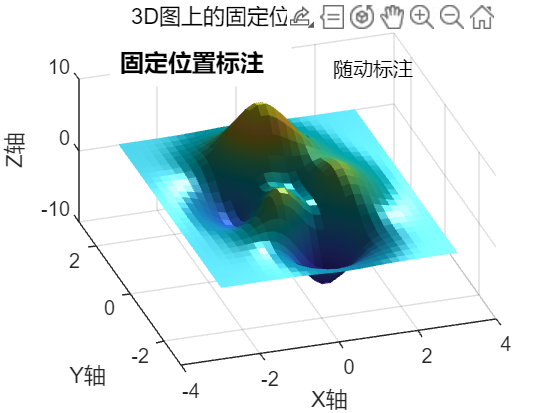

shading interp

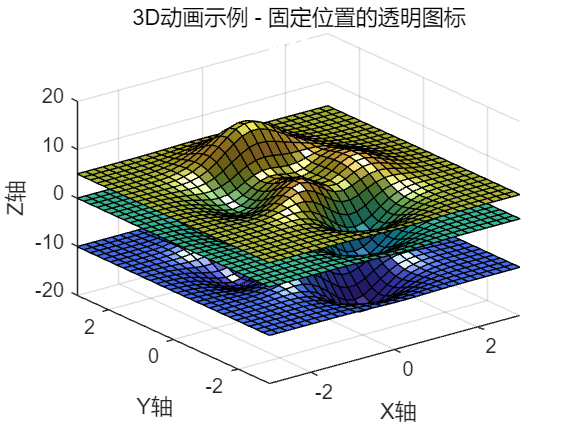

% 创建示例数据
[x, y, z] = peaks(30);

% 创建3D图
figure;
mainAxis = axes;
surf(x, y, z);
hold on;

% 设置轴属性
xlabel('X轴');
ylabel('Y轴');
zlabel('Z轴');
title('3D动画示例 - 固定位置的透明图标');
grid on;

% 设置光源
light('Position', [15 15 10], 'Style', 'infinite');

% 读取PNG图标
[iconImg, ~, iconAlpha] = imread('COMPASS_icon.png');



% 创建固定位置的图标注释
dim = [0.15 0.8 0.4 0.2]; % [x, y, width, height] 相对于figure的归一化坐标
iconAnnotation = annotation('textbox', dim, 'FitBoxToText', 'off', 'EdgeColor', 'none');
iconAnnotation.Position = dim; % 位置

% 将图标添加到注释
iconAxes = axes('Position', dim, 'Units', 'normalized','HitTest','off');
iconFig = imshow(iconImg, 'Parent', iconAxes);
set(iconAxes, 'color', 'none', 'XColor', 'none', 'YColor', 'none'); % 去除坐标轴
set(iconFig,'AlphaData',iconAlpha)

surf(x, y, z+5,'Parent',mainAxis);


surf(x, y, z-10,'Parent',mainAxis);